clear all; close all; clc;

p = load("gnss_data.csv");

T = 1;

A = [1 T T^2/2 0; 0 1 T 0; 0 0 1 1; 0 0 0 1];
C = [1 0 0 0];

mia = [5 0 -5];
deva = [5 1 5];
vara = (deva./3).^2;


Q = [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 1]*vara(1);
R = 100;
%inicijalizacija

x_est = [0; 0; 5; vara(1)];
P_est = eye(4);

x_estimirano = zeros(4, length(p) + 1);
P_estimirano = zeros(4, length(p) + 1);
K_ = zeros(4,length(p));

x_estimirano(:,1) = x_est;
P_estimirano(:,1) = [P_est(1,1);P_est(2,2);P_est(3,3);P_est(4,4)];
cnt = 1;
for i = 1:100
    if i == 31
        cnt = cnt + 1;
        Q = [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 1]*vara(cnt);
        x_est = [x_estimirano(1, i); x_estimirano(2, i); mia(cnt); x_estimirano(4,i)];
        P_est = P_estimirano(i);
    end
    if i == 71
        cnt = cnt + 1;
        Q = [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 1]*vara(cnt);
        x_est = [x_estimirano(1, i); x_estimirano(2, i); mia(cnt); x_estimirano(4,i)];
        P_est = P_estimirano(i);        
    end
    x_pred = A*x_est;
    P_pred = A*P_est*A' + Q;    
    if i < 40 || i > 60
        K = P_pred*C'*(C*P_pred*C' + R)^-1;
        x_est = x_pred + K*(p(i) - C*x_pred);
        P_est = (eye(4) - K*C)*P_pred;        
    else
        if i < 45
            R = (sqrt(R) + 10)^2;
            K = P_pred*C'*(C*P_pred*C' + R)^-1;
            x_est = x_pred + K*(p(i) - C*x_pred);
            P_est = (eye(4) - K*C)*P_pred;
        elseif i >= 45 && i < 56
             x_est = x_pred;
             P_est = P_pred;
             K = 0;
        else
            R = (sqrt(R) - 10)^2;
            K = P_pred*C'*(C*P_pred*C' + R)^-1;
            x_est = x_pred + K*(p(i) - C*x_pred);
            P_est = (eye(4) - K*C)*P_pred;
        end        
    end
    x_estimirano(:, i+1) = x_est;
    P_estimirano(:, i+1) = [P_est(1,1);P_est(2,2);P_est(3,3);P_est(4,4)];
    K_(:,i) = K; 
end

P_2int = 2*sqrt(P_estimirano)

P_2int = 	1.0e+03 *

    0.0020    0.0030    0.0058    0.0101    0.0144    0.0167    0.0175    0.0177    0.0179    0.0179    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0180    0.0153    0.0175    0.0185    0.0188    0.0188    0.0186    0.0183    0.0180    0.0177    0.0263    0.0375    0.0494    0.0612    0.0728    0.1052    0.1477    0.2018    0.2694    0.3522
    0.0020    0.0028    0.0047    0.0082    0.0125    0.0155    0.0171    0.0181    0.0187    0.0191    0.0193    0.0195    0.0196    0.0196    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0197    0.0190    0.0227    0.0271    0.0277    0.0252    0.0222    0.0196    0.0175    0.0158    0.0192    0.0225    0.0253    0.0277    0.0300    0.0392    0.0501    0.06

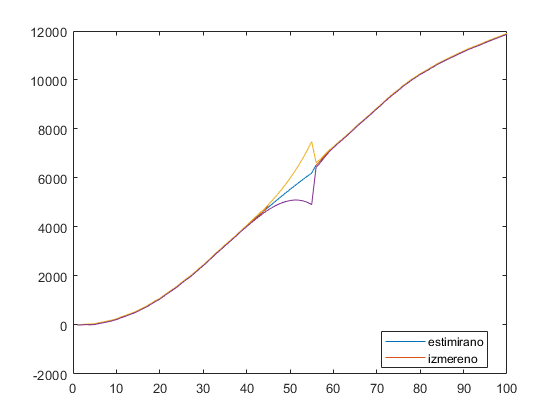

tplot = 1:1:100;
figure(1)
plot(tplot, x_estimirano(1,2:end))
hold on;
plot (tplot, p, tplot, x_estimirano(1,2:end)+P_2int(1,2:end),...
    tplot, x_estimirano(1,2:end) - P_2int(1,2:end));
legend('estimirano','izmereno','Location','best')

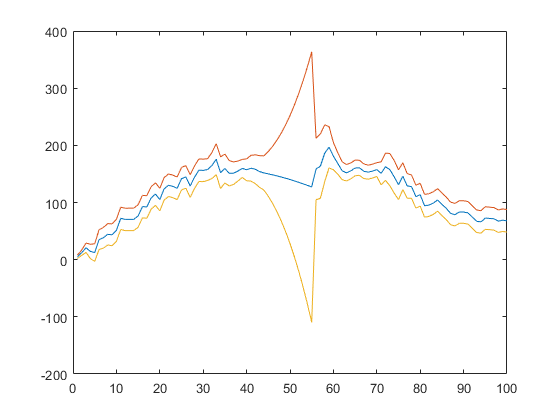

figure(2)
plot(tplot, x_estimirano(2,2:end), tplot, x_estimirano(2,2:end)+P_2int(2,2:end),...
    tplot, x_estimirano(2,2:end) - P_2int(2,2:end));

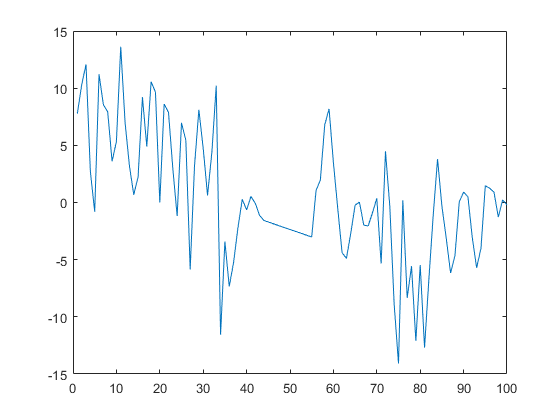

figure(3)
plot(tplot, x_estimirano(3,2:end));

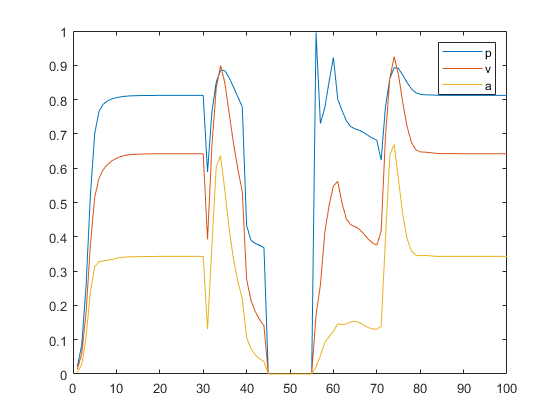

figure(4)
plot(tplot, K_(1,:),tplot,K_(2,:),tplot,K_(3,:));
legend('p','v','a')